# LEDS Exam

clear all
close all
addpath ./Functions;

## Exercise 1: ESTIMATION

In this exercise we estimate an unknown linear model.

### 1.1) Understand the model structure:

% We inizialize the data. 

N=10000;                 % Number of sample.
Student = 'Luca Santoro';
Matriculation = '0001005415';

% We collect the measures.

[Measurements] = IdentifyThis(N,Student,Matriculation);
u=Measurements.u;
y=Measurements.y;

As a first step, to understand if we are working with an **AR** or **ARX **model we can take a look at our input u.

disp(u);                 % We display the components of input vector u.

   -2.1847
   -2.2693
    3.7333
   -1.7751
   -8.2846
   -2.8900
    3.3014
    1.0830
   -2.2452
    0.7799
    2.7099
    3.6710
   -4.4203
    0.7862
    2.4990
    3.0331
    2.7705
   -2.7349
   -2.1722
    6.5176
   -2.1367
   -5.2987
   -3.2358
    1.2590
   -3.1822
   -1.3937
    5.5299
    2.9629
    2.1123
   -5.4693
   -0.1727
   -3.3455
   -6.3156
   -2.5649
    1.4302
   -5.3035
    0.1823
    0.3984
   -2.8003
    2.8180
    3.2050
    5.4725
   -0.6710
    1.5732
   -1.4137
    2.3064
    1.7551
    5.2353
   -1.1833
    2.8667
   -3.9004
   -1.6635
    3.8889
    5.2187
    1.9870
    4.4701
    0.7834
   -4.0815
   -6.8483
   -4.4654
   -4.8241
    4.4501
   -0.7958
   -0.7617
   -0.5209
   -3.1643
    5.8567
    5.7126
    2.7168
   -3.2922
    1.2035
    1.4796
   -6.3354
    2.6078
   -5.1563
   -1.4624
    5.6849
    0.5622
    2.6904
    3.2348
   -4.1330
    4.8060
   -1.0100
    2.9984
   -0.2147
   -3.9001
    1.9127
   -1.6650
   -2.2868
   -2.3751
    0.0439

From the above result, we can see that our input is different from a vector of zeros, so it means that our model has a input, like the ARX model.

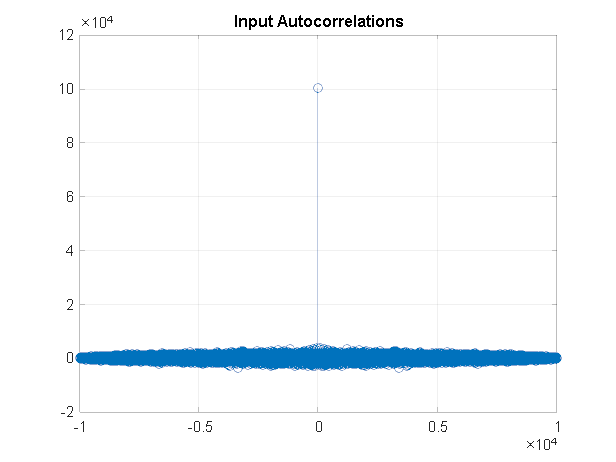

figure();

[c,lags] = xcorr(u);  % The function xcorr(u) returns the autocorrelation sequence of u.
stem(lags,c)
grid on;
hold on;
zoom on;
title('Input Autocorrelations');

To get a better graph and a more readable result we use the **autocorr ()** function. As required in the exam text, we plot the input autocorrelations up to delay 10.

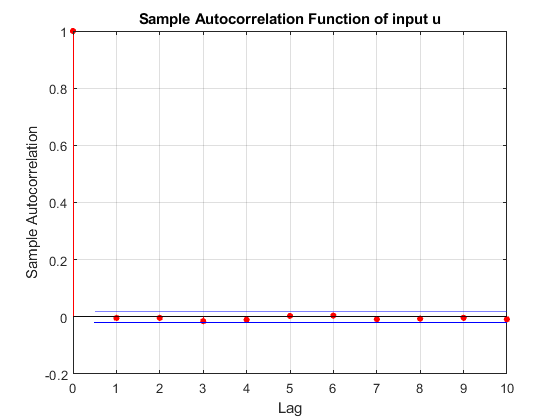

figure()        % We plots the sample autocorrelation function of u with confidence bounds.
autocorr(u,10);
title('Sample Autocorrelation Function of input u');

The above graph, presents autocorrelation coefficients and the confidence intervals. If the autocorrelation coefficient is in the confidence interval, it is regarded as not statistically significant. Therefore, we should focus on the values where the value of the ACF is outside the confidence interval.

In general, if we have a  white process means that successive samples are uncorrelated, in other words, the autocorrelation function of white process is an impulse at lag 0.

In the figure above we see that the only autocorrelation value outside the 95% confidence interval occurs at delay 0 as expected in the case of a white process. Based on this result, we can conclude that the input data u is a realization of a white  process.

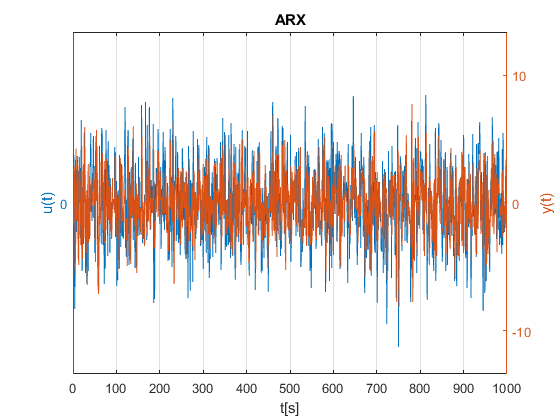


figure();    % We plot the trend of the output and the input of our ARX model.

time=[0:1:N-1]';
ax=plotyy(time(1:1000),u(1:1000),time(1:1000),y(1:1000));
grid on;
ylabel(ax(1),'u(t)');
ylim(ax(1),[-max(y)*1.5 max(y)*1.5]);

ylabel(ax(2),'y(t)');
ylim(ax(2),[-max(y)*1.5 max(y)*1.5]);
xlabel('t[s]');
title('ARX');

At the end, our **model is ARX****.**

### 1.2) Define the required estimation algorithm:

The model structure to be analyzed is Autoregressive exogenous model (**ARX**). The ARX equation is given by: 


$$\mathit{\mathbf{y}}\left(\mathit{\mathbf{t}}\right)+{a_1 y\left(t-1\right)+\ldotp \ldotp \ldotp +a_n y\left(t-n\right)=\;\mathit{\mathbf{b}}}_1 \;\mathit{\mathbf{u}}\left(\mathit{\mathbf{t}}-1\right)+{\mathit{\mathbf{b}}}_2 \;\left(\mathit{\mathbf{t}}-2\right)\;+\ldotp \ldotp \ldotp \ldotp \ldotp +{\mathit{\mathbf{b}}}_{\mathit{\mathbf{n}}} \;\mathit{\mathbf{u}}\left(\mathit{\mathbf{t}}-\mathit{\mathbf{n}}\right)+\varepsilon \left(\mathit{\mathbf{t}}\right)$$


In which $y\left(t\right)$is the output, $u\left(t\right)$the input and $\varepsilon \left(t\right)$ a white process with 0 mean and variance $\sigma_{\varepsilon }^2$.

The previous equatiion can be rewritten in the Linear regression form and once the measurements are available we can compute our algorithm to estimate the model parameters.

Linear regression form:     $y\left(t\right)=\varphi^T \left(t\right)\;\theta +\varepsilon \left(t\right)$     where    $\varphi \left(t\right)={\left\lbrack -y\left(t-1\right)\;\ldotp \ldotp \ldotp -y\left(t-n\right)\;\;u\left(t-1\right)\;\ldotp \ldotp \ldotp u\left(t-n\right)\right\rbrack }^T ={\left\lbrack -\varphi_y^T \;\;\varphi_u^T \right\rbrack }^T$  ,       $\theta ={\left\lbrack {a_1 \ldotp \ldotp \ldotp a_n \;b}_1 \ldotp \ldotp \ldotp b_n \right\rbrack }^T$                 

To comply with the specific request in the exam text (recursive version of the estimation algorithm), we use the Recursive Least Square algorithm **RLS III **since this not require the inversion of the matrix, so we don't have to make the inversion of the square matrix $S\left(t\right)$ or $R\left(t\right)$ at each step. This is a computational advantage (less calculations). 

**How does it work?**

This kind of recursive algorithm update the estimate of the parameters of the model with the data received a time **t** (so the new sample) using the estimation of the parameters with data collected up to time **t-1 **(so the old data already estimated). So this algorithm is more computationally efficient and save a lot of memory since there is no need to recalculate everything once a new data is availble. Practically when new data is available we can update $\hat{\theta} \left(t\right)$ starting from $\hat{\theta} \;\left(t-1\right)$.

We haven't estimated the model order hence we don't have n. Now since we need to know the order of the model to use the algorithm,  we consider a model order **n = 5 **.

To define the required estimation algorithm we have implemented first of all the function **myPhi.m** which generate the vector $\varphi \left(t\right)={\left\lbrack \;-y\left(t-1\right)\;\ldotp \ldotp \ldotp -y\left(t-n\right)\;u\left(t-1\right)\ldotp \ldotp \ldotp \ldotp \ldotp u\left(t-n\right)\right\rbrack }^{T\;\;}$ thath collect the input and output samples. Then we can implement the function **myRLS_III **that allow to perform the RLS III algorithm. Within the function we have explained everything in more detail...

n = 5                       % Our choice for the order estimation.

n = 5

thetahat = myRLS_III(y,u,n) % We estimate the model parameters using the RLS III algorithm.

thetahat =     0.2641
    0.3248
   -0.0000
   -0.0027
   -0.0002
    0.6363
    0.2641
   -0.0025
    0.0006
    0.0018


### 1.3) Estimate the model order:

At this point  we need to estimate the model order to understand if our order is suitable and which is the proper order to adopt. To do this we can use ''criteria with complexity term'' that allow to find a minimum in correspondence of the true order. As fist step we implement the function **myHank.m** that generate the Hankel matrix that allow us to realize the function **myCostFunc.m** which defines the Cost function and then we can find the minimum avoiding underfitting and overfitting. 

In particular, since the number of sample is high we choose the **MDL **criterion (Minimum Description Lenght) because leads to models of lower complexity and so it should give the best solution with respect to the **AIC **(Akaike information criterion) and **FPE **(Final prediction error) criteria. FPE and AIC are asymptotically  equivalent. With **AIC** and **FPE** we could have more probability of overestimating the order, they are less consistents. in addition, the results may not be reliable: running the script multiple times can result in a different result each time.

                                                    
$$\textrm{AIC}=N\;l\;\textrm{og}\;J\left({\hat{\theta} }_N \right)+2p$$
                                                   
$$\textrm{FPE}=\frac{N+p}{N-p}\;J\left({\hat{\theta} }_N \right)\approx J\left({\hat{\theta} }_N \right)+\frac{2p}{N}\;J\left({\hat{\theta} }_N \right)$$


So, by defining the function **myMDL.m** we can compute the criteria and estimate the model order. (For a better understanding of the functions see the comments within the functions themselves).

                                                                                           
$$\textrm{MDL}=N\;\log \;J\left({\hat{\theta} }_N \right)+2p\;\log \;N$$


Below we apply the Minimun Description lenght - **MDL**

L=15;             % We check the orders up to order n=15

% MDL CRITERION

for n=1:L
    thetahat=myRLS_III(y,u,n);     
    J(n)=myMDL(y,u,thetahat);
end

[value,n_min]=min(J);
disp('MDL:');

MDL:


% We show the minimum value we found and its order.
disp('min J - n');

min J - n


disp([value, n_min]);

   35.6305    2.0000



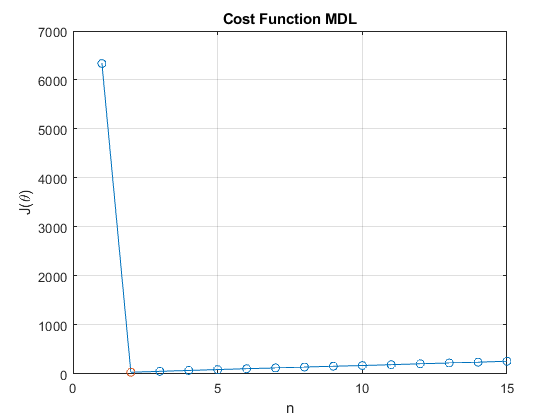


figure();        % Cost Function MDL

plot(J,'-o');
grid on;
hold on;
plot(n_min,J(n_min),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function MDL');

We can use Cross Validation to get a better result. We can use it because we have a larger number of samples. In particular ,we can split in half our set of measure. One half is used for the definition of the model also the other half is used to gather cost function. Doing that we are able to perform a better assessment of the complexity  our model.

% MDL with validation set.
for n=1:L
    thetahat=myRLS_III(y(1:N/2),u(1:N/2),n);   %  We split the data set to check the robustness of the result. Hence, training set from 1 to 1/N.
    J(n)=myMDL(y(N/2+1:end),u(N/2+1:end),thetahat);
end

[value,n_min]=min(J);
disp('MDL with C.V:');

MDL with C.V:


% We show the minimum value we found and its order.
disp('min J - n');

min J - n


disp([value, n_min]);

    5.1990    2.0000



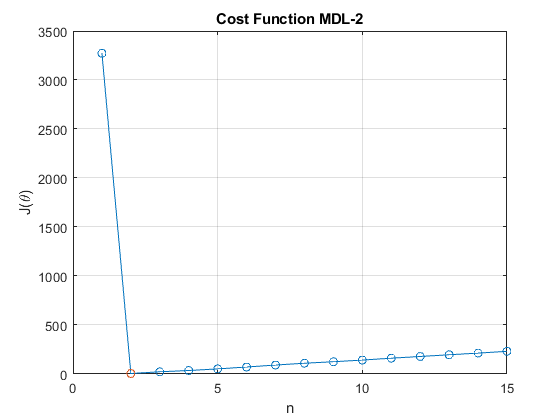


figure();   % Cost Function MDL using C.V. (Better result)

plot(J,'-o');
grid on;
hold on;
plot(n_min,J(n_min),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function MDL-2');

Below, we try to compute **FPE** and** AIC **using the functions **myFPE.m **and **myAIC.m,** to evaluate the difference compared to MDL. We can see that the results are less clear. So we consider **MDL** which allows us to get a better result.

% FPE CRITERION:

for n=1:L
    thetahat=myRLS_III(y,u,n);
    J(n)=myFPE(y,u,thetahat);
end

[value,n_min]=min(J);
disp('FPE:');

FPE:


% We show the minimum value we found and its order.
disp('min J - n');

min J - n


disp([value, n_min]);

    1.0003    2.0000



figure();   % Cost Function MDL and Cost Function MDL using C.V.

subplot(1,2,1) % Is it working, we get 2 as the value that minimizes the cost function, but the result is not so clear and may exist ambiguities.

plot(J,'-o');
grid on;
hold on;
plot(n_min,J(n_min),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function FPE');

% We can use Cross Validation to get a better result
for n=1:L
     thetahat=myRLS_III(y(1:N/2),u(1:N/2),n);   %  We split the data set ( from 1 to 1/N).
    J(n)=myFPE(y(N/2+1:end),u(N/2+1:end),thetahat);
end

[value,n_min]=min(J);
disp('FPE with C.V:');

FPE with C.V:


% We show the minimum value we found and its order.
disp('min J - n');

min J - n


disp([value, n_min]);

    0.9950    2.0000



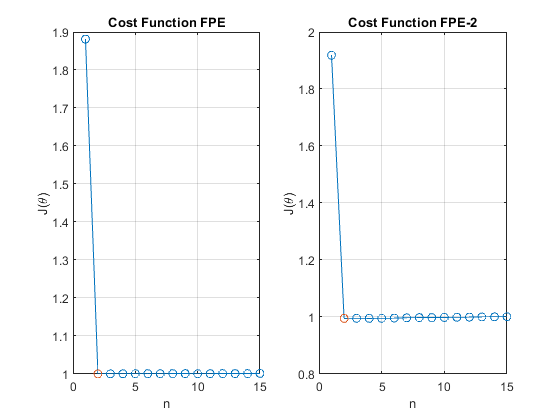

subplot(1,2,2);

plot(J,'-o');
grid on;
hold on;
plot(n_min,J(n_min),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function FPE-2');

% AIC CRITERION:

for n=1:L
    thetahat=myRLS_III(y,u,n); 
    J(n)=myAIC(y,u,thetahat);
end

[value,n_min]=min(J);
disp('AIC:');

AIC:


% We show the minimum value we found and its order.
disp('min J - n');

min J - n


disp([value, n_min]);

    2.7892    2.0000



figure();   % Cost Function AIC and Cost Function AIC using C.V.

subplot(1,2,1);

plot(J,'-o');
grid on;
hold on;
plot(n_min,J(n_min),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function AIC');

% As in the previous cases we can use Cross Validation to get a better
% result.
for n=1:L
     thetahat=myRLS_III(y(1:N/2),u(1:N/2),n);   %  We split the data set. Hence, training set from 1 to 1/N.
    J(n)=myAIC(y(N/2+1:end),u(N/2+1:end),thetahat);
end

[value,n_min]=min(J);
disp('AIC with C.V:');

AIC with C.V:


% We show the minimum value we found and its order.
disp('min J - n');

min J - n


disp([value, n_min]);

  -24.8698    2.0000



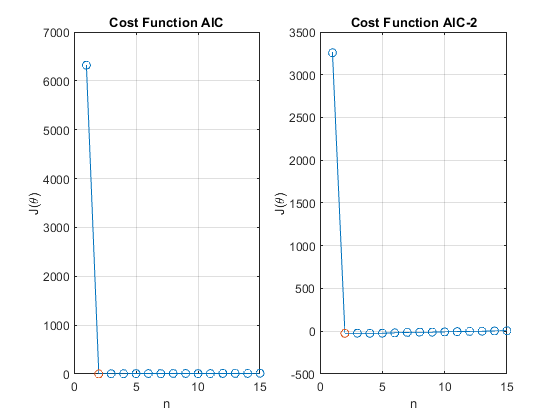

subplot(1,2,2);

plot(J,'-o');
grid on;
hold on;
plot(n_min,J(n_min),'o');
ylabel('J(\theta)');
xlabel('n');
title('Cost Function AIC-2');

As previously mentioned and as highlighted in the graphs, the **MDL** criterion produces a better result.From the previous results we can conclude that the correct order is n = 2.

### 1.4) Validate the model:

At this point we have to  evaluate the capability of the identified model to describe the process that has generated the data in a way compatible with its planned use. 

At the beginning of this exercise we arbitrarily chose an order for our model equal to 5 (n = 5). From the previous point it is clear that our choice is not correct. The analysis carried out leads to the choice of the order equal to 2 (n=2).

**The proper order is n = 2**, so now we consider this order and we estimate the new model using the RLS III.

n_proper=2;
thetahat=myRLS_III(y,u,n_proper);
disp('thetahat:');

thetahat:


disp(thetahat);

    0.2643
    0.3286
    0.6357
    0.2640



To validate the model we have to solve two statistical hypotesys tests. In particular, we have to check if the residual $\varepsilon \left(\mathit{\mathbf{t}},\theta \right)$ is a zero mean white process and if the residual is uncorrelated with the input signal $u\left(t\right)\ldotp$

- **FIRST TEST**

The first test is the so called **Whiteness test** where the two hypothesis are:


$$\left\lbrace \begin{array}{ll}
H_0 :\varepsilon \left(t,\theta \right)\;\;\textrm{is}\;a\;\textrm{zero}\;\textrm{mean}\;\textrm{white}\;\textrm{process} & \\
H_1 :\textrm{not}\;H_0  & 
\end{array}\right.$$


Computing the function **myWhiteness_norm.m **we obtain the normalized test quantities

 
$$\overset{\wedge }{\gamma} \;\left(\tau \right)=\frac{\hat{r_{\varepsilon } \;} \left(\tau \right)}{\hat{r_{\varepsilon } \;} \left(0\right)}$$
 

and with the function **MyAnderson_test.m **we are able to make the **Anderson test **in order to understand which hypothesis is correct. (Open the functions for a more in-depth explanation).

H=[-myHank(y,n_proper) myHank(u,n_proper)];  % We calculate Hankel Matrix. 
 
e=y(n_proper+1:end)-H*thetahat;              % We find the residual. 

% At this point we can consider the normalized test quantity and we can compute the
% test to understand if the residual is a zero mean white process.

gamma=myWhiteness_norm(e);
alpha=0.05;                                  % We fix alpha to 0.05 (50%) for the Anderson test.
disp('Anderson test result:');

Anderson test result:


disp(MyAnderson_test(alpha,gamma,N));

H0 accepted


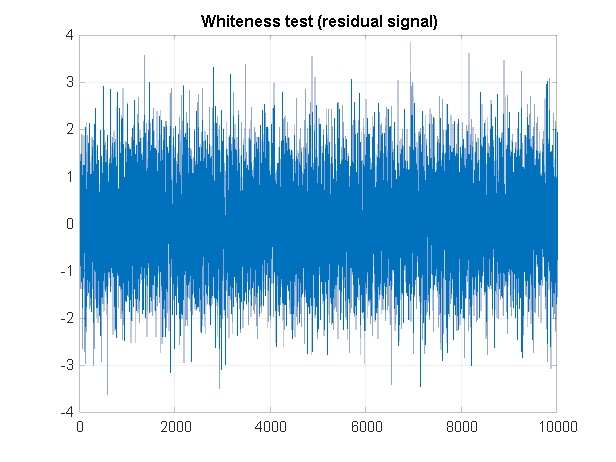

figure();

plot(e);
grid on;
hold on;
zoom on;
title('Whiteness test (residual signal)');

The test is satisfied and we accept the hypotesys $H_0$, so this means that the residual is a zero mean white process.

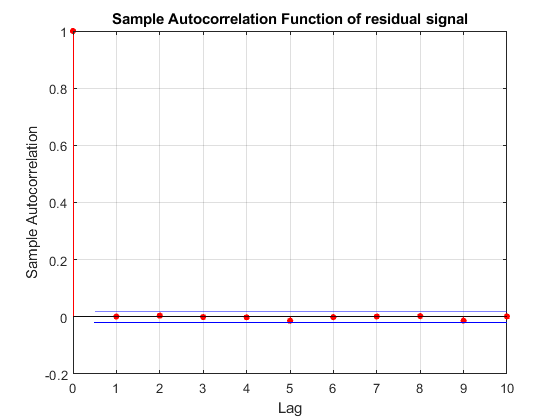

figure();
autocorr(e,10);
title('Sample Autocorrelation Function of residual signal');

- **SECOND TEST**

Now we compute the second test with similar steps, called test of **Cross-Correlation** where the two hyphotesis are:


$$\left\lbrace \begin{array}{ll}
H_0 :\varepsilon \left(t,\theta \right)\;\textrm{and}\;u\left(t\right)\;\textrm{are}\;\textrm{uncorrelated} & \\
H_1 :\textrm{not}\;H_0  & 
\end{array}\right.$$


The function **myCC_norm.m **allow us to find the normalized test quantities :


$$\overset{\wedge }{\gamma} \;\left(\tau \right)=\frac{\hat{r_{\varepsilon } \;} \left(\tau \right)}{\sqrt{\hat{r_{\varepsilon } \;} \left(0\right)\;\hat{r_u \;} \left(0\right)}}$$
 

As in the previous test we use the function **MyAnderson_test.m** to obtain the correct hypothesis.

% Now we check if the residual is uncorrelated with the input.
gammaC=myCC_norm(e,u);
alpha=0.05;
disp('Anderson test result:');

Anderson test result:


disp(MyAnderson_test(alpha,gammaC,N));

H0 accepted


Also in this case the hypothesis $H_0$ is satisfied and so $\varepsilon \left(t,\theta \right)$ and $u\left(t\right)$ are uncorrelated. Finally, thanks to these results we can accept and validate our model with order n=2.

## Exercise 2: CLASSIFICATION

In this exercise we create a classificatior from a training set and test it on a new test set..

We want to solve a classification problem using the Logistic Regression with the Newton-Raphson Algorithm.

### 2.1) Understand the feature set in space:

To get all the samples of the training set and the test set we invoke the **ClassifyThis.p** function with the appropriate inputs. As a first step we plot the training features to understand how they are scattered in space.

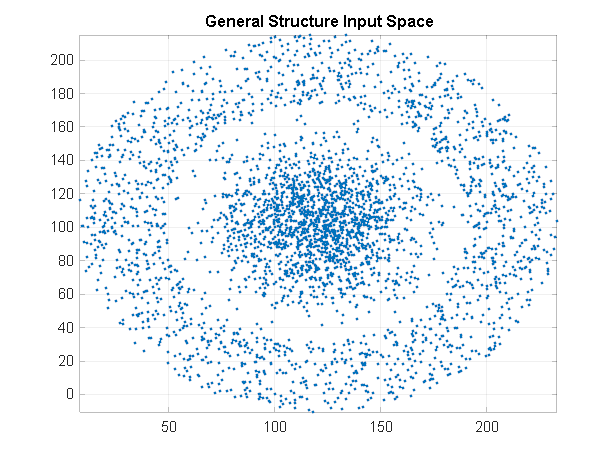

N=5000;                      % Number of total samples (integer).
Student = 'Luca Santoro';
Matriculation = '0001005415';
[FeatureSet] = ClassifyThis(N,Student,Matriculation);

Utrain  = FeatureSet.Utrain;  % This piece of code allows you to collect the set.   
Ytrain  = FeatureSet.Ytrain;
Utest   = FeatureSet.Utest;

Ntrain=size(Utrain,1);
Ntest=size(Utest,1);

figure();                     % Plotting the training features we can see how are scattered in the space.
plot(Utrain(1:end,1),Utrain(1:end,2),'.');
hold on 
grid on
zoom on
axis tight                    % We fit the axes box tightly around the data by setting the axis limits equal to the range of the data.               
title('General Structure Input Space');

As we can see from the previous graph of the general input structure, we have two possible classes. We call them **C**`I `and** C**`II`. We trace them differently to better distinguish them. In particular we want to find a possible decision boundary.

U=mean(Utrain);
Utrain=Utrain-U;

U0=Utrain(find(Ytrain<0.5),:); % We devide inputs in two different classes.
U1=Utrain(find(Ytrain>0.5),:);
Y0=Ytrain(find(Ytrain<0.5));
Y1=Ytrain(find(Ytrain>0.5));

figure();                      % Graph of the two classes, to find a boundary.

plot(U0(1:end,1),U0(1:end,2),'.');
hold on 
grid on 
zoom on 
plot(U1(1:end,1),U1(1:end,2),'.');
title('Divided Input Space');


As we can see from the following graph, in this case, the best decision boundary is an ellipse (not a circle).

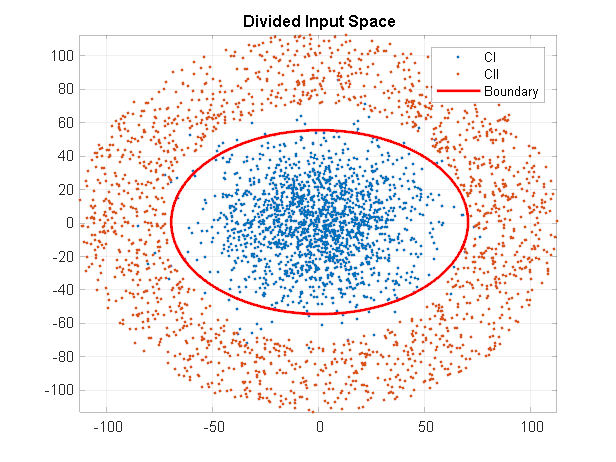

t = linspace(0,2*pi);           % Generic Elliptic Boundary, to understand that elliptic boundary is better than circular boundary.
xx = 70*cos(t);
yy = 55*sin(t);
plot(xx,yy,'-r',"LineWidth",2)

axis tight
hold off
legend({'CI','CII','Boundary'});

From the graph we can see that the decision boundary is nonlinear decision boundary. We have an elliptical boundary. It is not a problem to have** nonlinear model** as long as it is linear in parameters.

 A nonlinear boundary in input space U can be mapped into a linear one in a **trasformed space** $\bar{U}$.

                                                                      
$$u\left(t\right)\in U\;\;\longrightarrow \bar{u} \left(t\right)=g\left(u\left(t\right)\right)\in \bar{U}$$


Function `g`() is nonlinear transformation of vector $u\left(t\right)$ into $\bar{u} \left(t\right)$.

In general if we have a circular boundary, the two spaces are of the same size:  $U=\bar{U} =\Re^2$. However, in general the dimension of $\bar{U}$ is greather than that of the original input space U and the complexity of the model increases.

                  Circular Decision Boundary :         $\;\;u\left(t\right)=\left\lbrack \begin{array}{c}
u_0 \left(t\right)\\
u_1 \;\left(t\right)
\end{array}\right\rbrack \;\;\;\;\;\longrightarrow \;\bar{u} \left(t\right)=\left\lbrack \begin{array}{c}
u_0^2 \left(t\right)\\
u_1^2 \left(t\right)
\end{array}\right\rbrack$                 $U=\bar{U}$

                  Elliptic Decision Boundary :           $\;\;u\left(t\right)=\left\lbrack \begin{array}{c}
u_0 \left(t\right)\\
u_1 \;\left(t\right)
\end{array}\right\rbrack \;\;\;\;\;\longrightarrow \;\bar{u} \left(t\right)=$$\left\lbrack \begin{array}{c}
u_0 \left(t\right)\\
u_1 \;\left(t\right)\\
u_0^2 \left(t\right)\\
u_1^2 \left(t\right)
\end{array}\right\rbrack$                $U\le \bar{U}$              (our case)

It is possible to achieve nonlinear decision boundaries by using the higher order polynomial terms. We can use this transformed training set to apply Logistic Regression, and the ellipse will become a hyperplane.

We can use the** KERNEL  TRICK** , the general idea is to map the original input space to some higher dimensional trasformed space where the training set is separable. The kernel trick provides a more efficient and less expensive (less computation) way to transorm data into larger dimension. Through the kernel function the two-dimensional ellipse is mapped into a three-dimensional hyperplane, as shown in the following figure:

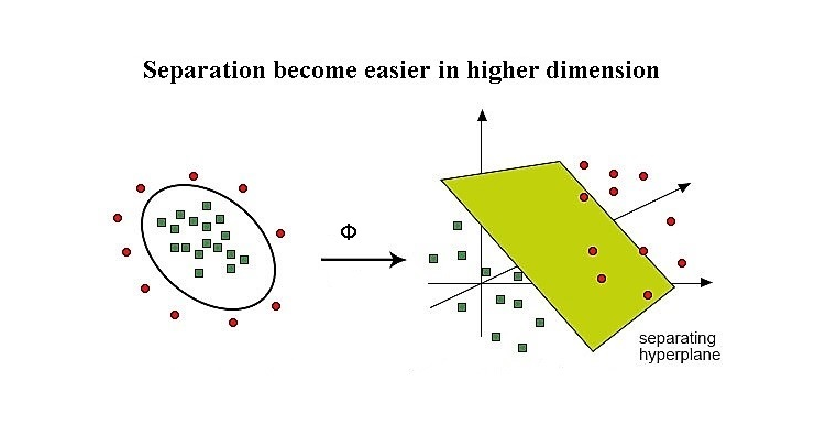

imshow(imread("Separating_Hyperplane.jpg"))

                                                                    
$$\begin{array}{l}
\phi :\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Re^2 \longrightarrow \Re^3 \\
\;\;\;\;\;\;\;\;\;\;\;\;\left(u_0 ,u_1 \right)\longmapsto \left(z_1 ,z_2 ,z_3 \right)=\left(u_0^2 ,\sqrt{2}u_0 u_1 ,u_1^2 \right)\;\;\;\;\;\;\;\;\;
\end{array}$$
   

If we try to linearly separate the mapped data, our decision boundaries will be hyperplane in $\Re^3$, of the form $w^T z+b=0$, i.e as function of u they will be of the form :

                                                                              
$${w_1 \;u}_0^2 +w_2 \;\sqrt{2}u_0 u_1 +w_3 \;u_1^2 =0$$


which is the equation of an ellipse.

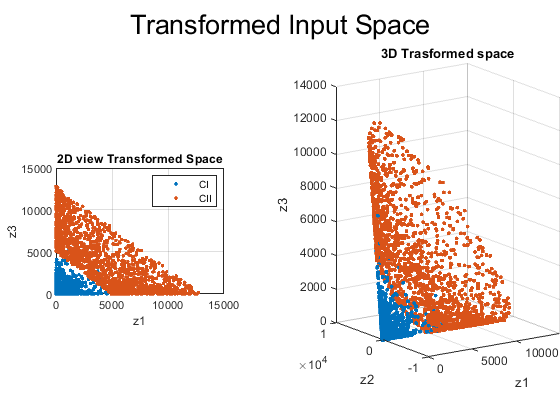

figure();                      % Transformed Input space. 
% We map the nonlinear input space into a linear space (Transformed Space).
sgt = sgtitle('Transformed Input Space');
sgt.FontSize = 20;

pos1 = [0.1 0.3 0.3 0.3];
subplot('Position',pos1)       % 2D View Transformed Space.
plot(U0(1:end,1).^2,U0(1:end,2).^2,'.');  
grid on;
hold on;
plot(U1(1:end,1).^2,U1(1:end,2).^2,'.');
xlabel('z1');
ylabel('z3');
legend({'CI','CII'});
title('2D view Transformed Space')

pos2 = [0.6 0.15 0.4 0.7];
subplot('Position',pos2)        % 3D Transformed Space.
plot3(U0(1:end,1).^2,sqrt(2)*((U0(1:end,1)).*(U0(1:end,2))),U0(1:end,2).^2,'.'); 
grid on;
hold on;
plot3(U1(1:end,1).^2,sqrt(2)*((U1(1:end,1)).*(U1(1:end,2))),U1(1:end,2).^2,'.');
xlabel('z1');
ylabel('z2');
zlabel('z3');
view(-35,10);                  % Display settings.
title('3D Trasformed space');

### 2.2) Define the required classification algorithm:

We want to apply Logistic regression so to get a classificator able to distinguish unknown samples taken from the test dataset. **Logistic Regression** is a classification model. It is a simple and more efficient method for binary and linear classification problems. It is very easy to do and achieves excellent performance with linearly separable classes. The Logistic Regression algorithm is obtained according **maximum likelihood estimation**, thus pursuing the decision boundary that maximizes the probability of getting correct labels. 

In generar to do this we need a decision boundary, which is an an hyperplane with the following equation:

                                                   $\beta_0$+$\beta_1 u_1 \left(t\right)$+$\beta_2 u_2 \left(t\right)$+ ..... + $\beta_r u_r \left(t\right)$ = 0

That can be rewritten in the linear regression form:

$\varphi \left(t\right)={\left\lbrack 1\;\;u_1 \left(t\right)\;\;u_2 \left(t\right)\;\ldotp \ldotp \ldotp u_r \left(t\right)\;\right\rbrack }^T$           $\theta$ = ${\left\lbrack \;\beta_1 \;\;\;\beta_2 \;\;\;\ldotp \ldotp \ldotp {\;\beta }_r \;\right\rbrack }^T$            $\Longrightarrow$            $\varphi^T$$\theta$ = 0

 The our problem becomes an optimization problem  where we need a function f(z(t)), where z(t) = $\varphi^T$$\theta$ , that approximate the probability P($C_1 |u\left(t\right)$). The logistic sigmond function is defined with the function **sigmoidfunc.m**.

We need the cost function function derived through the rules of maximum likelihood estimation, which is:

                              
$$\;J\left(\theta \right)=\textrm{logP}\left(Y|\theta \right)=\sum_{t\;=1}^N \left\lbrack y\left(t\right)\log \;f\left(z\left(t\right)\right)+\;\left(1-y\left(t\right)\right)\;\log \left(1-f\left(z\left(t\right)\right)\right)\;\right\rbrack$$
 

In general, the estimate theta  $\hat{\theta}$  minimizing $J\left(\theta \right)=\;-\textrm{logP}\left(Y|\theta \right)$ cannot be found analytically $\Longrightarrow$ iterative identification algorithms (The **Newton - Raphson Algorithm**):

                                                         
$${\hat{\vartheta} }^{\;K+1} ={\hat{\vartheta} }^{\;K} -\alpha_{\;k} {\;J}^{\prime \prime } {\left({\hat{\vartheta} }^{\;K} \right)}^{-1} {\;J}^{\prime } {\left({\hat{\vartheta} }^{\;K} \right)}^T$$


Thanks to the Newton-Raphson algorithm we can approximate the cost function to a quadratic function using the Taylor expansion around ${\hat{\theta} }^k$ and truncating it after quadratic term, in this way we can update the parameter obtaining ${\hat{\theta} }^{k+1}$.

As first step we define $\varphi \left(t\right)$ = [$1\;u_0 \left(t\right)\;u_1 \left(t\right)$]' but in trasformed way.

Ut=[ Utrain(1:end,1).^2  sqrt(2)*((Utrain(1:end,1)).* (Utrain(1:end,2))) Utrain(1:end,2).^2 ];  % We work with linearized input

PHITrain=[ones(Ntrain,1) Ut];  % ϕ=[1 ū]' , where ū =[z1 z2 z3]=[u0^2 sqrt(2)*(u0)*(u1) u1^2]     warning: u1 is different to U1 (same observation for u0).
Theta=[0;0;0;0];               % We initialize the algorithm with θ as a vector of zero. It can also chosen randomly.

Once the all values are available we inizialize the cost functionvand we apply the Newton-Raphson algorithm to solve our optimization problem. To do this we follow the following points:

- we first find the Gradient and the Hessian of the cost function, respectively throught the functions **LRCostFuncGrad.m** and **LRCostFuncHessian.m**.

- we update the $\theta$ value through Newton - Raphson..

- we minimize the cost function, we use the **LRCostFunc.m** to find the new value of J (which will decrease for each new k).

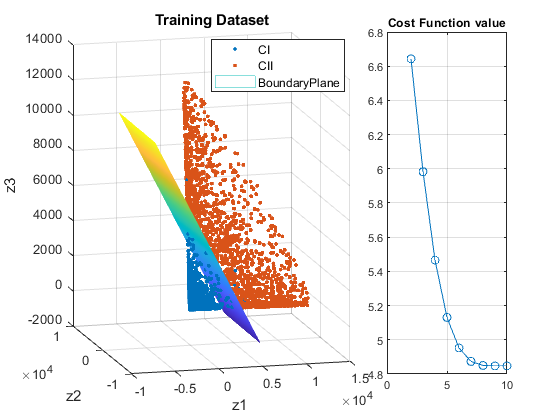

Alpha = 1; 
%{
Alpha is used to control the step lenght, and represent the speed of updating the parameters and the inclination of the boundary.
To obtain a faster simulation we have chosen Alpha = 1 (In general alpha is smaller for example 0.01).
%}
J(1)=1000;
k=2;

figure();

while 1
    
    F=Sigmoid(PHITrain*Theta);
    gradJ = LRCostFuncGrad(PHITrain,Ytrain,Theta);  % We compute the gradient of J(θ). 
    HessJ=LRCostFuncHessian(PHITrain,Ytrain,Theta); % We compute the Hessian of J(θ).
    Theta = Theta - Alpha*inv(HessJ)*gradJ;         % We compute the Newton-Raphson algorithm.
    J(k)=-LRCostFunc(PHITrain,Ytrain,Theta);        % Once we have θ updated we minimize the cost function. 
    if (abs(J(k)-J(k-1))<0.001)                     % Accuracy of the Boundary plane, the algorithm will stop when two consecutive J(K) will be lower than 0.001.    
        break;
    end

%  PLOTS OF OUR RESULTS:   
     
     subplot(1,3,[1 2]);                            % 3D Trasformed Space.
     scatter3(U0(1:end,1).^2,sqrt(2)*((U0(1:end,1)).*(U0(1:end,2))),U0(1:end,2).^2,'.'); 
     grid on
     hold on
     scatter3(U1(1:end,1).^2,sqrt(2)*((U1(1:end,1)).*(U1(1:end,2))),U1(1:end,2).^2,'.');
     
     
     [xx yy] = meshgrid(-6*10^3:100:6*10^3);       % This piece of code allows us to define and plot the decision Boundary Hyperplane.
     BoundaryPlane= (Theta(1) + xx.*Theta(2) + yy.*Theta(3))./(-Theta(4));
     mesh(xx,yy,BoundaryPlane);
     xlabel('z1');
     ylabel('z2');
     zlabel('z3');
     
     
    
    hold off
    title('Training Dataset');
    legend({'CI','CII','BoundaryPlane'});
    legend('Location','best');                      % Legend settings.
    view(-15,10);                                   % Display settings.
    
    subplot(1,3,3);             
    %{ 
     Graph of Cost Function: When we want to look the evolution of our algorithm in terms of cost 
     or in terms of descent it would be much better to plot it in a logarithmic scale.
     For this reason we use a LOGARITHMIC SCALE on vertical axis.
    %}
    plot(2:k,log(abs(J(2:k))),'o-');
    grid on;
    title('Cost Function value')
    
    pause(0.1);
    k=k+1;
end

disp('Theta values:');

Theta values:


disp(Theta);

  -13.7419
    0.0029
   -0.0000
    0.0030



.

### 2.3) Verify and test your classificator:

In this last point we test our classifier and calculate the **Classification Error**. In particular, we compare our classifier with the classifier provided by matlab and graphic the results obtained and compare them.

In order to obtain the the multinominal logistic regression of Matlab we use the function **mnrfit()**.

ThetaMatlab = mnrfit(Ut,Ytrain+1);
disp('Theta and ThetaMatlab values:');

Theta and ThetaMatlab values:


disp([Theta ThetaMatlab])

  -13.7419   13.7419
    0.0029   -0.0029
   -0.0000    0.0000
    0.0030   -0.0030



PHITest=[ones(Ntrain,1) Ut];
Yhat = Sigmoid(PHITest*Theta);
Yhat = double(Yhat>0.5);
ClassificationError = 1/(Ntrain)*((abs(Yhat-Ytrain))'*(abs(Yhat-Ytrain)))

ClassificationError = 0.0077

As we can see the **Classification Error** is 0.0077, which corresponds to 0,77% that we can approximate to **0.8%**, this is a low (good) value and therefore the classification should be good.

Below we report the results and compare them with the real ones:

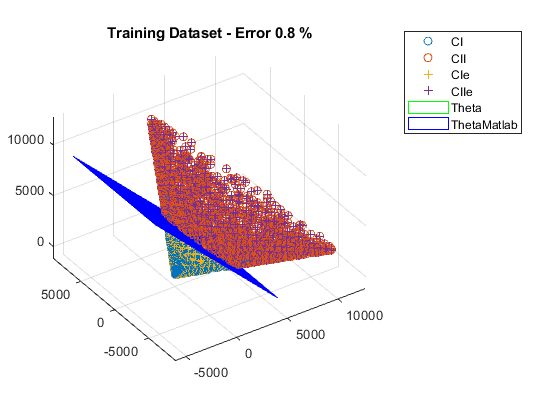

figure();

scatter3(U0(1:end,1).^2,sqrt(2)*((U0(1:end,1)).*(U0(1:end,2))),U0(1:end,2).^2,'o'); % 3D Transformed Space.
grid on
hold on
scatter3(U1(1:end,1).^2,sqrt(2)*((U1(1:end,1)).*(U1(1:end,2))),U1(1:end,2).^2,'o');

scatter3(Ut(find(Yhat<0.5),1),Ut(find(Yhat<0.5),2),Ut(find(Yhat<0.5),3),'+'); 
grid on
hold on
scatter3(Ut(find(Yhat>0.5),1),Ut(find(Yhat>0.5),2),Ut(find(Yhat>0.5),3),'+');
 
[xx yy] = meshgrid(-6*10^3:100:6*10^3);       % This piece of code allows us to define and plot the decision Boundary hyperplanes.
BoundaryPlane= (Theta(1) + xx.*Theta(2) + yy.*Theta(3))./(-Theta(4));
mesh(xx,yy,BoundaryPlane,'edgecolor', 'g'); 
hold on 
BoundaryPlaneB= (ThetaMatlab(1) + xx.*ThetaMatlab(2) + yy.*ThetaMatlab(3))./(-ThetaMatlab(4));
mesh(xx,yy,BoundaryPlaneB,'edgecolor', 'b');
Title =  sprintf('Training Dataset - Error %3.1f %%',ClassificationError*100);
title(Title);
legend({'CI','CII','CIe','CIIe','Theta','ThetaMatlab'},'location','bestoutside');
axis equal;
view([-34 34]);                               % Display settings.

As can be seen from the previous figure, the two boundary hyperplanes coincide, this is because the theta values provided by matlab are very similar to those obtained by us. Furthermore, we have a fairly small classification error.

Below, we use our classificator on the test set provided in the exam text. We do this to check our classificator.

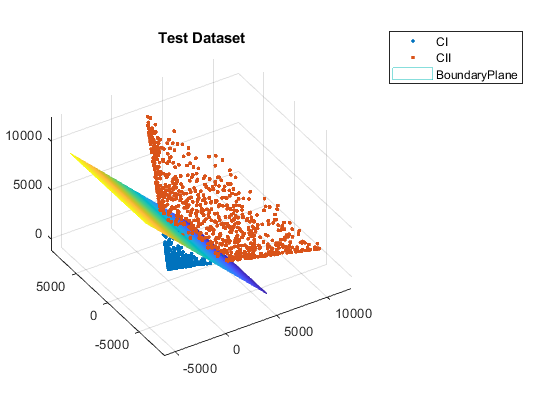

Um=mean(Utest);
Utest=Utest-Um;

Ute=[ Utest(1:end,1).^2  sqrt(2)*((Utest(1:end,1)).* (Utest(1:end,2))) Utest(1:end,2).^2 ];  
PHITest=[ones(Ntest,1) Ute];

Yhat = Sigmoid(PHITest*Theta);
Yhat = double(Yhat>0.5);

figure();
scatter3(Ute(find(Yhat<0.5),1),Ute(find(Yhat<0.5),2),Ute(find(Yhat<0.5),3),'.'); 
grid on
hold on
scatter3(Ute(find(Yhat>0.5),1),Ute(find(Yhat>0.5),2),Ute(find(Yhat>0.5),3),'.');

[xx yy] = meshgrid(-6*10^3:100:6*10^3);       % This piece of code allows us to define and plot the decision Boundary hyperplane.
BoundaryPlane= (Theta(1) + xx.*Theta(2) + yy.*Theta(3))./(-Theta(4));
mesh(xx,yy,BoundaryPlane); 
title('Test Dataset');
legend({'CI','CII','BoundaryPlane'});
axis equal;
view([-32 35]);                               % Display settings.